# Bag of Features

clear; clc;

imagem = imread('..\Dataset\77\16_L_N_L_BH_1.tif');

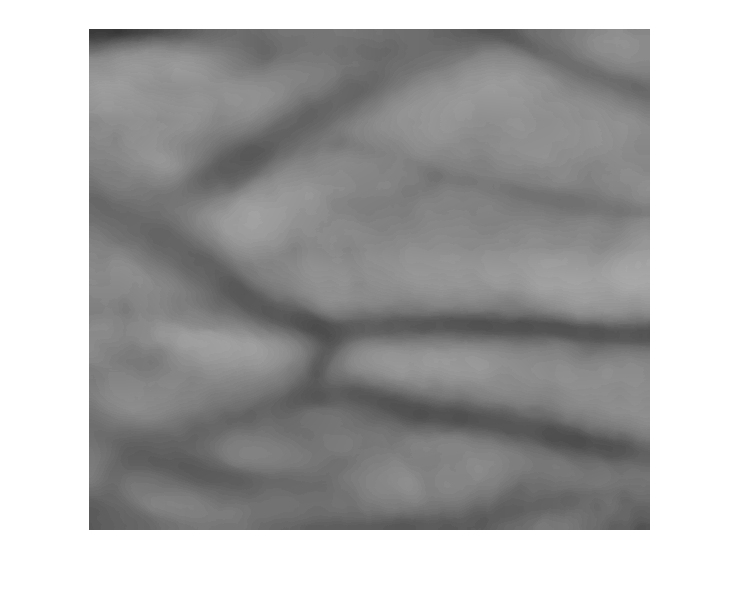

centroid = [360, 520];
d1 = 250;
d2 = 280;

E1 = (centroid(1) - d1):(centroid(1) + d1);
E2 = (centroid(2) - d2):(centroid(2) + d2);

ROI = imagem(E1,E2);

ROI = medfilt2(ROI, [16,16],'symmetric');
    
adaptHistEqual = adapthisteq(ROI);

I = adaptHistEqual;
imshow(adaptHistEqual)

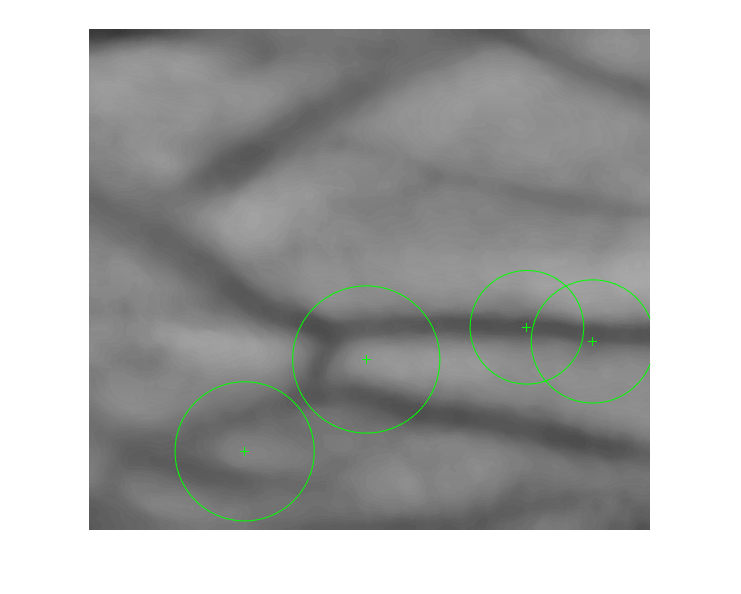

points = detectSURFFeatures(adaptHistEqual, "MetricThreshold", 320);
imshow(adaptHistEqual); hold on;
plot(points);

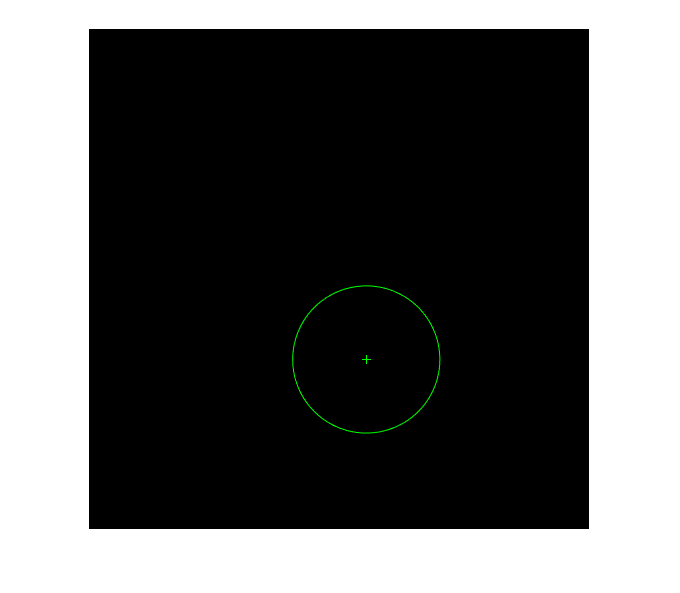

imagem2 = imrotate(adaptHistEqual,0);
imagem2 = imresize(imagem2, 2);
imagem2 = uint8(zeros(500,500));
[features, valid_points] = extractFeatures(imagem2, points);
imshow(imagem2); hold on;
plot(valid_points)